clear; clc;
dataQtd = 100;
centersQtd = 4;
epochQtd = 50;

#### 1 - Define o conjuto de dados 

data1 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(5,dataQtd,1)+15]-randi(3,dataQtd,1);
data2 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)+15]-randi(5,dataQtd,1);
data3 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(3,dataQtd,1);
data4 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(4,dataQtd,1);

data = [data1; data2; data3; data4];

#### 2 - Inicializa os centros dos grupos

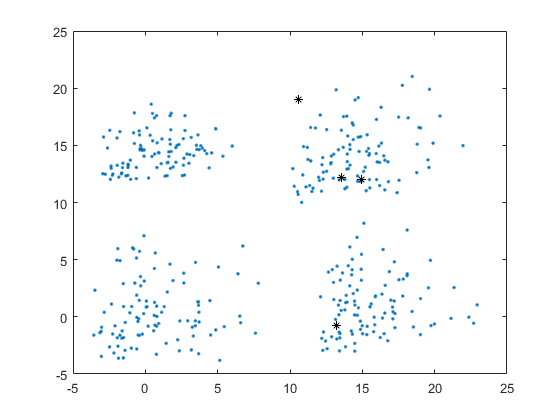

centers = [];
for i = 1:1:centersQtd
    centers = [centers; [data(randi(length(data),1,1),1), data(randi(length(data),1,1),2)]];
end

figure(1); 
plot(data(:,1), data(:,2), '.', ...
    centers(:,1), centers(:,2), '*k');

#### Inicia o loop de eventos

pertinence = linspace(0,0,length(data));
for i=1:1:epochQtd
    for j=1:1:length(data)
        pertinence(j) = distance(data(j,:),centers);
    end
    centers = recalculateCenter(pertinence, data, centers);
end

#### Plota os resultados

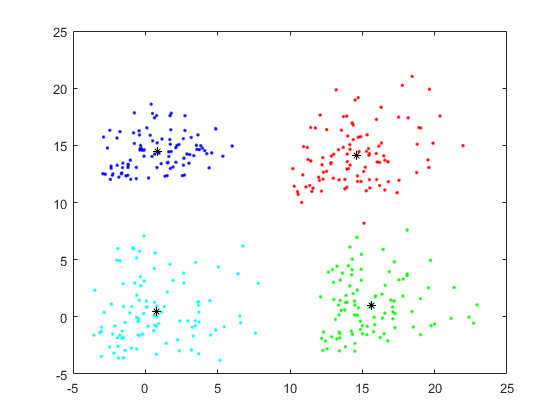

colors = ['r', 'g', 'b', 'c', 'm', 'y', 'w'];
figure(2);
plot(data(1,1), data(1,2), strcat('.',colors(pertinence(1)))); hold on
for i=2:1:length(data)
    plot(data(i,1), data(i,2), strcat('.',colors(pertinence(i))));
end
plot(centers(:,1), centers(:,2), '*k'); hold off;

#### Test com outra base de dados

define novos dados

data1 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(5,dataQtd,1)+15]-randi(3,dataQtd,1);
data2 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)+15]-randi(5,dataQtd,1);
data3 = [rand(dataQtd,1).*randi(10,dataQtd,1)+15, rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(3,dataQtd,1);
data4 = [rand(dataQtd,1).*randi(10,dataQtd,1),    rand(dataQtd,1).* ...
    randi(10,dataQtd,1)]-randi(4,dataQtd,1);

Passa os dados no modelo

cont1 = 0; cont2 = 0; cont3 = 0; cont4 = 0;
for j=1:1:length(data)
    pertinence(j) = distance(data(j,:),centers);
    if(pertinence(j) == 1)
        cont1 = cont1 + 1;
    elseif (pertinence(j) == 2)
        cont2 = cont2 + 1;
    elseif (pertinence(j) == 3)
        cont3 = cont3 + 1;
    elseif (pertinence(j) == 4)
        cont4 = cont4 + 1;  
    end
end

err = abs(cont1-100) + abs(cont2-100) + abs(cont3-100) + abs(cont4-100);
fprintf("Acertos: %d | Erros: %d", 400-err, err);

Acertos: 398 | Erros: 2

Plota a classificação

colors = ['r', 'g', 'b', 'c', 'm', 'y', 'w'];
figure(2);
plot(data(1,1), data(1,2), strcat('.',colors(pertinence(1)))); hold on
for i=2:1:length(data)
    plot(data(i,1), data(i,2), strcat('.',colors(pertinence(i))));
end
plot(centers(:,1), centers(:,2), '*k'); hold off;

#### Functions

realiza os calculos da distância do ponto até o centro pelo metodo euclidiano

function res = distance(sample, centers)
    dist = linspace(0,0,length(centers));
    for i=1:1:length(centers)
        sm = 0;
        for j=1:1:length(sample)
            sm = sm + (sample(j)-centers(i,j))^2;
        end
        dist(i) = sqrt(sm);
    end
    [val res] = min(dist);
end

recalcula a posição do centro

function res = recalculateCenter(pertinence, data, centers)
    [qtd, dimensity] = size(data);
    sumEle = zeros(length(centers),dimensity);
    sumQtd = linspace(0,0,length(centers));
    
    for i=1:1:qtd
        it = pertinence(i);
        for j=1:1:dimensity
            sumEle(it,j) = sumEle(it,j) + data(i,j);
        end 
        sumQtd(it) = sumQtd(it)+1;   
    end
    
    for i=1:1:length(centers)
        for j=1:1:dimensity
            if sumQtd(i) > 0
                centers(i,j) = sumEle(i,j)/sumQtd(i);
            end   
        end
    end
    res = centers;    
end